# Zadanie 4 - Analityczne rozwiązanie

# równania Poissona dla złącza Shotky-ego w przybliżeniu obszaru cąłkowicie zubożonego i z uwzględnieniem nosników swobodnych

Nc=6.2e15*300^(3/2);
Nv = 3.5e15*300^(3/2);
Eg=1.12;%%[eV]

domieszkowanie półprzewodnika typu n w złączu [${\textrm{cm}}^{-3}$] zadane przez użytkwonikia:

Nd_mantysa=7.9;Nd_potega=14; 
Nd=Nd_mantysa*10^(Nd_potega);%%[cm^-3]
k=1.381e-23;%[J/K]
q=1.602e-19;%%[C]
epsilon_0=8.854187817e-12;%%[F/m]
epsilon_r=11.68;
epsilon=epsilon_r*epsilon_0;%%[F/m=A^2*s^4/(kg*m^3)]
n_i=sqrt(Nc*Nv)*exp(-Eg*q/(2*k*300));%%[cm^-3]
Ei=Eg/2;
Ef_n=-log(Nd/n_i)*k/1.6e-19*300+Ei;%%[eV]
V_bi=2*log(Nd/n_i)*k*300/q;%%[V]
W=sqrt(2*epsilon/q*V_bi*(1/Nd))/10.0;%%[sqrt(F/m/C*V*(cm^3))=sqrt(A^2*s^4*V*cm^3/(kg*m^3*C))=sqrt(cm^3/m)=sqrt(cm^2*0.01m/m)=cm*0.1]*10-> [cm]
x_n=W;%%[cm]

## Komentarz,wykresy i wyniki dla rozwiązania w przybliżeniu obszaru całkowicie zubożonego

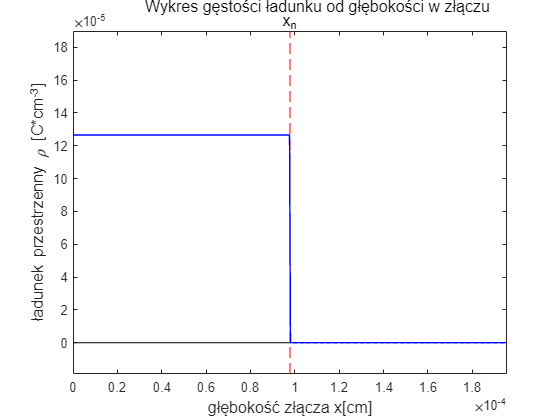

X=0:2*x_n/499.0:2*x_n;%%[cm]
%%h=x_n/499.0;
rho=zeros(size(X));%%[C*cm^-3]
for i=1:size(X,2)
        if(X(1,i)<x_n)
        rho(1,i)=q*Nd(1);%%[C*cm^-3] 
        end      
end 
E_el=zeros(size(X));
E_el(size(X,2))=0;%%max(rho)*1e-3;
V=zeros(size(X)); %%[V]
Ld=sqrt(epsilon*k*300/q/q/Nd)/10;%% [cm]
V(size(X,2))=-k*300/q*exp(-x_n/Ld);
for i=size(X,2):-1:2
    E_el(i-1)=E_el(i)+rho(i)/epsilon*(X(i-1)-X(i))*100;
    V(i-1)=V(i)-E_el(i)*(X(i-1)-X(i));
end

plot([min(X) max(X)], [0 0], 'Color', 'k');
hold on
xlim([0,x_n*2.0]);
ylim([-max(rho)*0.15,max(rho)*1.5]);
plot([x_n x_n], [-max(rho)*0.15,max(rho)*1.5], 'Color', 'red','LineStyle','--');
xlabel("głębokość złącza x[cm]","FontSize",12);
ylabel("ładunek przestrzenny \rho [C*cm^{-3}]","FontSize",12);
text(x_n-0.42e-5,max(rho)*1.54,"x_n","FontSize",12);
plot(X,rho,'color','blue','Linewidth',1.1)
text(x_n/3, max(rho)*1.62,'Wykres gęstości ładunku od głębokości w złączu','FontSize', 12);
hold off

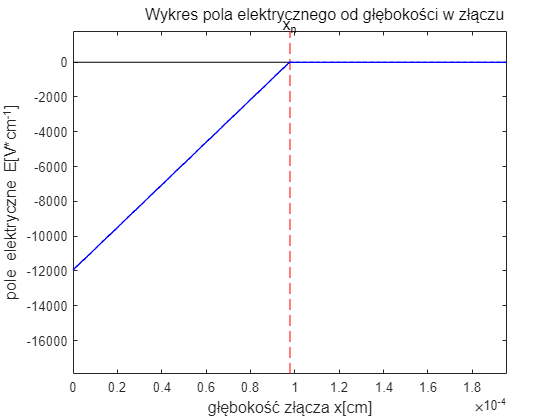


plot([min(X) max(X)], [0 0], 'Color', 'k');
hold on
xlim([0,x_n*2.0]);
ylim([min(E_el)*1.5,-min(E_el)*0.15]);
plot([x_n x_n], [min(E_el)*1.5,-min(E_el)*0.15], 'Color', 'red','LineStyle','--');
xlabel("głębokość złącza x[cm]","FontSize",12);
ylabel("pole elektryczne E[V*cm^{-1}]","FontSize",12);
text(x_n-0.42e-5,-min(E_el)*0.17,"x_n","FontSize",12);
plot(X,E_el,'color','blue','Linewidth',1.1)
text(x_n/3, -min(E_el)*0.23,'Wykres pola elektrycznego od głębokości w złączu','FontSize', 12);
hold off

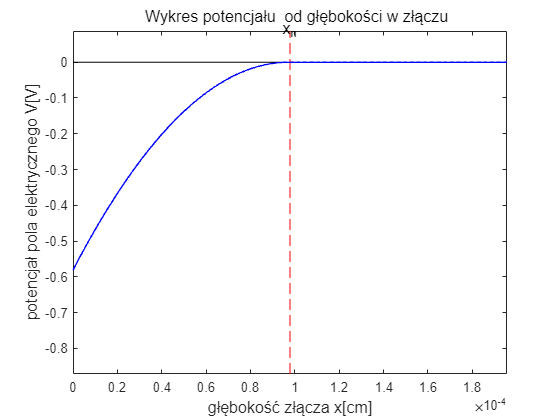


plot([min(X) max(X)], [0 0], 'Color', 'k');
hold on
xlim([0,x_n*2.0]);
ylim([min(V)*1.5,-min(V)*0.15]);
plot([x_n x_n], [min(V)*1.5,-min(V)*0.15], 'Color', 'red','LineStyle','--');
xlabel("głębokość złącza x[cm]","FontSize",12);
ylabel("potencjał pola elektrycznego V[V]","FontSize",12);
text(x_n-0.42e-5,-min(V)*0.15,"x_n","FontSize",12);
plot(X,V,'color','blue','Linewidth',1.1)
text(x_n/3, -min(V)*0.22,'Wykres potencjału  od głębokości w złączu','FontSize', 12);
hold off

Jak widać z przedstawionych wykresów po zastosowaniu metody eulera z odpowiednio małym krokiem, otrzymane wyniki są identyczne jak te uzyskane analitycznie.

## biorąc pod uwagę swobodne nośniki w obszarze zubożonym.

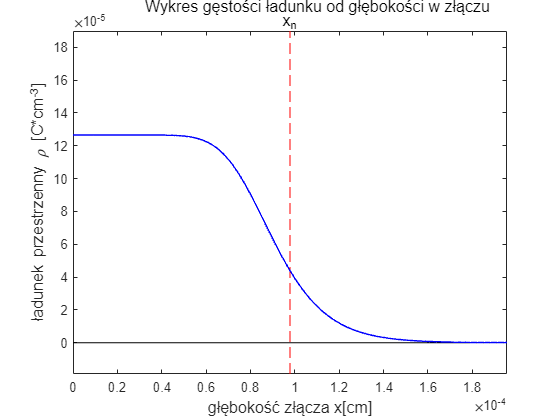

X=0:2*x_n/499.0:2*x_n;%%[cm]
%%h=x_n/499.0;
%%rho=q*Nd(1)*(1-exp(-q*V/k/300));%%zeros(size(X));%%[C*cm^-3]
E_el=zeros(size(X));
E_el(size(X,2))=0;%%max(rho)*1e-3;
V=zeros(size(X)); %%[V]
Ld=sqrt(epsilon*k*300/q/q/Nd)/10;%% [cm]
V(size(X,2))=-k*300/q*exp(-x_n/Ld);
for i=size(X,2):-1:2
    rho(i)=q*Nd(1)*(1-exp(q*V(i)/k/300));
    E_el(i-1)=E_el(i)+rho(i)/epsilon*(X(i-1)-X(i))*100;
    V(i-1)=V(i)-E_el(i)*(X(i-1)-X(i));
end

plot([min(X) max(X)], [0 0], 'Color', 'k');
hold on
xlim([0,x_n*2.0]);
ylim([-max(rho)*0.15,max(rho)*1.5]);
plot([x_n x_n], [-max(rho)*0.15,max(rho)*1.5], 'Color', 'red','LineStyle','--');
xlabel("głębokość złącza x[cm]","FontSize",12);
ylabel("ładunek przestrzenny \rho [C*cm^{-3}]","FontSize",12);
text(x_n-0.42e-5,max(rho)*1.54,"x_n","FontSize",12);
plot(X,rho,'color','blue','Linewidth',1.1)
text(x_n/3, max(rho)*1.62,'Wykres gęstości ładunku od głębokości w złączu','FontSize', 12);
hold off

Można zwrócić uwagę, że po uwzględnieniu swobodnych nośników rozkład gęstości wypłaszcza się. Wciąż większość elektronów skupia się na obszarze zubożonym lecz od około 2/3 tego obszaru gęstość ładunku zaczyna spdać eksponencjalnie do zera. Z tego powodu część ładunku wydostaje się poza obszar zubożony. Dodatkowo wraz ze zwiększeniem domieszkowania spadek gęstości ładunków staje się ostrzejszy, dąży do pinou czyli rozwiązania z przybliżenia. Może to oznaczać, że nośniki swobodne odgrywają tym mniejszą rolę na charakterystykę gęstości ładunku,pola elektrycznego i potencjału im większa jest koncentracja domoieszkowania.

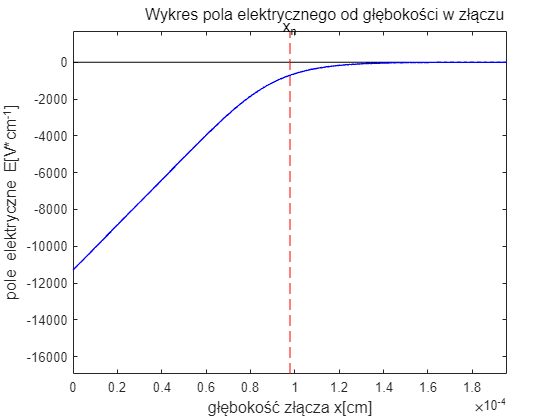

plot([min(X) max(X)], [0 0], 'Color', 'k');
hold on
xlim([0,x_n*2.0]);
ylim([min(E_el)*1.5,-min(E_el)*0.15]);
plot([x_n x_n], [min(E_el)*1.5,-min(E_el)*0.15], 'Color', 'red','LineStyle','--');
xlabel("głębokość złącza x[cm]","FontSize",12);
ylabel("pole elektryczne E[V*cm^{-1}]","FontSize",12);
text(x_n-0.42e-5,-min(E_el)*0.16,"x_n","FontSize",12);
plot(X,E_el,'color','blue','Linewidth',1.1)
text(x_n/3, -min(E_el)*0.23,'Wykres pola elektrycznego od głębokości w złączu','FontSize', 12);
hold off

Tak samo jak w poprzednim wykresie - z powodu obecności ładunku poza obszarem zubożonym otrzymano pole elektryczne poza obszarem zubożonym. Zależność pola od głębokości jest podobna jak w przybliżeniu ii jedynie wokół granicy obszaru zubożonego nieliniowo schodzi do 0.

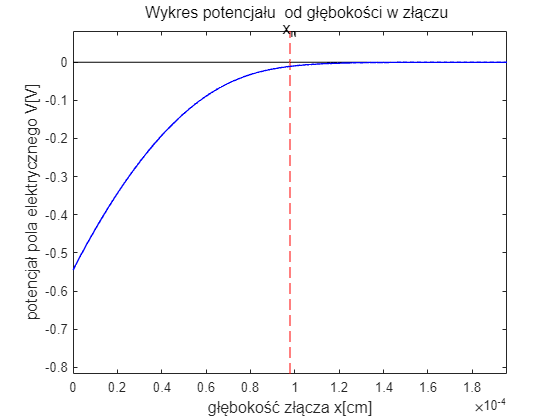

plot([min(X) max(X)], [0 0], 'Color', 'k');
hold on
xlim([0,x_n*2.0]);
ylim([min(V)*1.50,-min(V)*0.15]);
plot([x_n x_n], [min(V)*1.50,-min(V)*0.15], 'Color', 'red','LineStyle','--');
xlabel("głębokość złącza x[cm]","FontSize",12);
ylabel("potencjał pola elektrycznego V[V]","FontSize",12);
text(x_n-0.42e-5,-min(V)*0.15,"x_n","FontSize",12);
plot(X,V,'color','blue','Linewidth',1.1)
text(x_n/3, -min(V)*0.24,'Wykres potencjału  od głębokości w złączu','FontSize', 12);
hold off

Potencał różni się najmniej po uwzględnieniu swobodnych nośników. Zależność jest paraboliczna i potencjał minimalnie odbiega od tej zależności na granicy obszaru. Tak jak w poprzednich wielkościach, występuje potencjał poza obszarem zubożonym.

## Źródła:

[1] Instytut Fizyko Techniczny imienia A. F. Ioffego Rosyjskiej Akademii Nauk w Petersburgu

http://www.ioffe.ru/SVA/NSM/Semicond/Si